Here is the code that I used in the edge detection lecture.  You may substitute your own image.

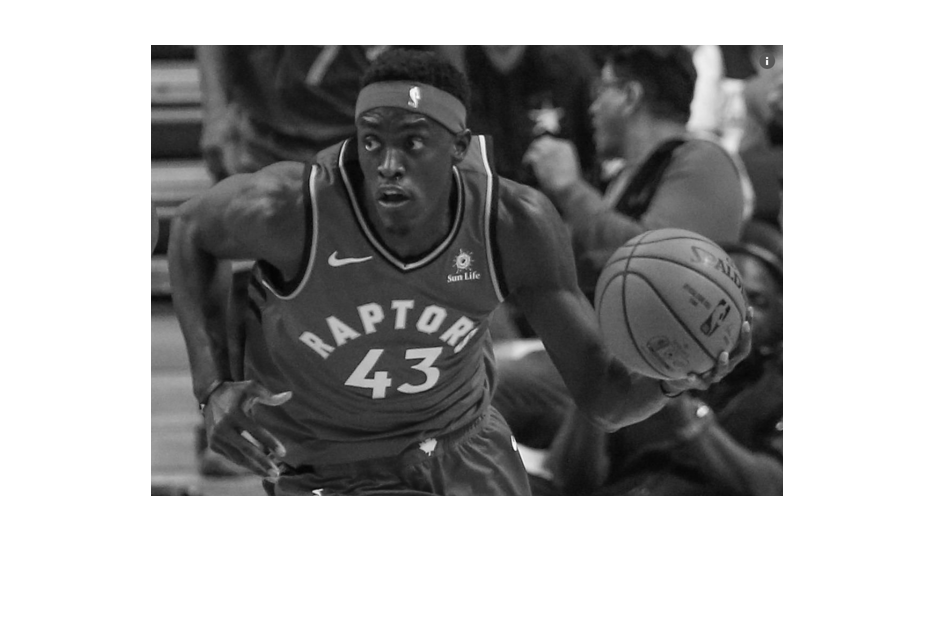

original = imread('IMAGES\PascalSiakam.png');
Igray = rgb2gray(original);
Igray = imresize(Igray, 0.5);
imshow(Igray);

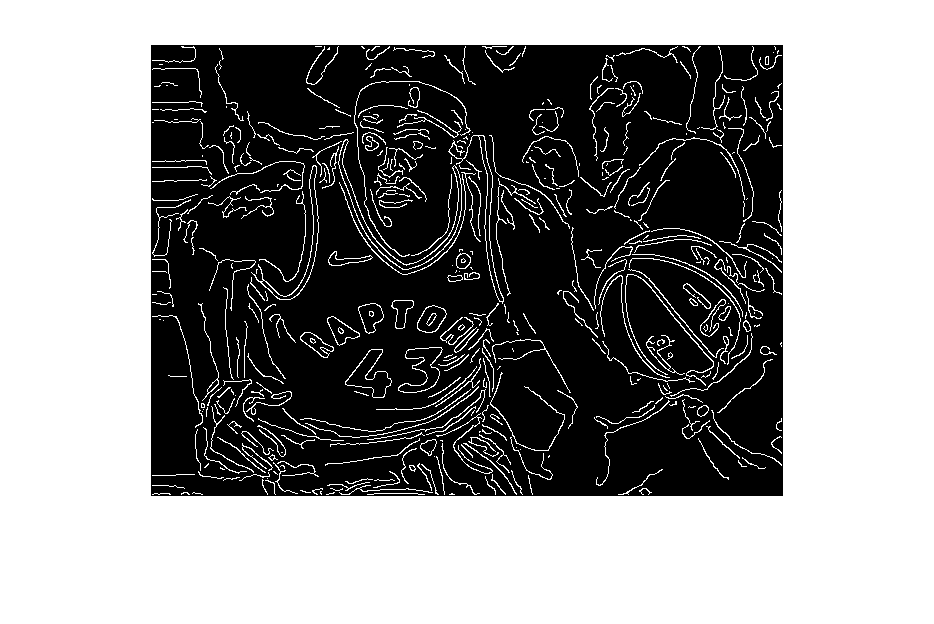

%Iedge = edge(Igray,'Canny',[.1 .2],2);
Iedge = edge(Igray,'Canny');
imshow(Iedge);

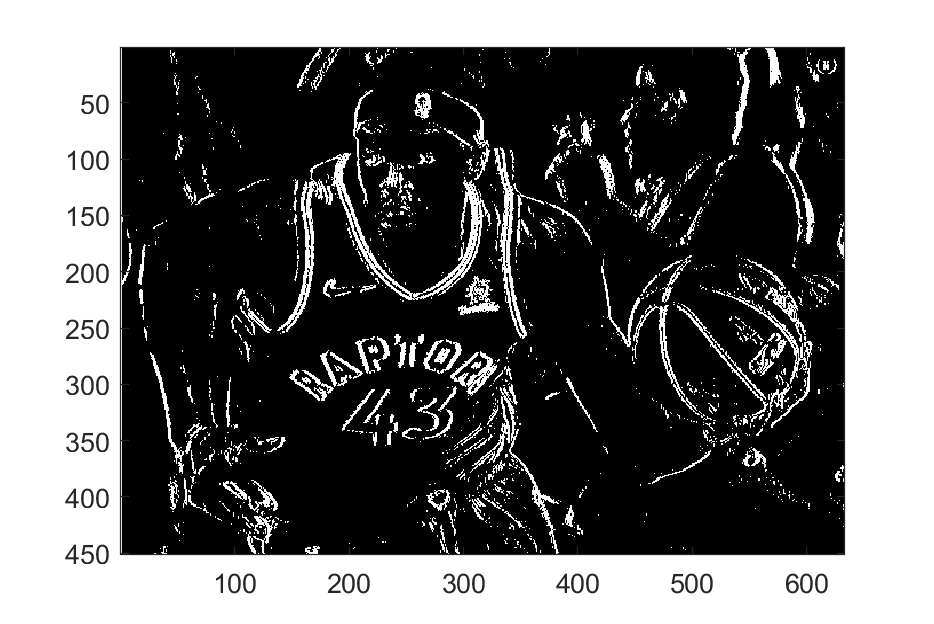

Inaive = abs(conv2(Igray,  [-1 1])) > 10;
imagesc( double(Inaive))
colormap gray

## Prewitt

%Here is a Prewitt like edge dector 
% close all
threshold = 100;
dIdx = conv2(Igray,  [1 0 -1; 1 0 -1;  1 0 -1]);
dIdy = conv2(Igray,  [1 0 -1; 1 0 -1;  1 0 -1]');
Inaive = sqrt( dIdx .* dIdx + dIdy .* dIdy) > 150;
%imagesc( double(Inaive))
colormap gray

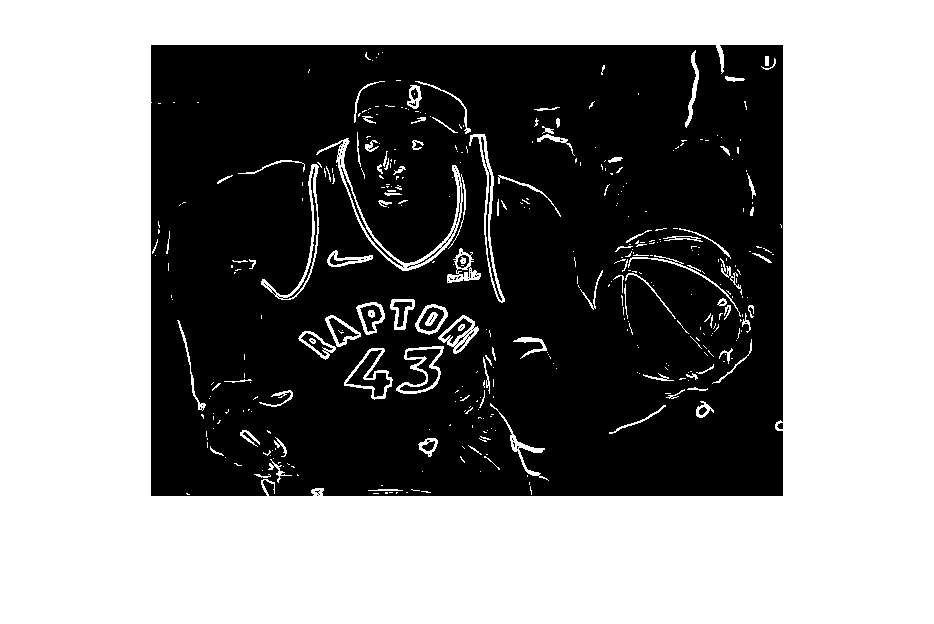

%Here is the actual Prewitt edge dector 
Iedge = edge(Igray,'Prewitt','nothinning');
imshow(Iedge);

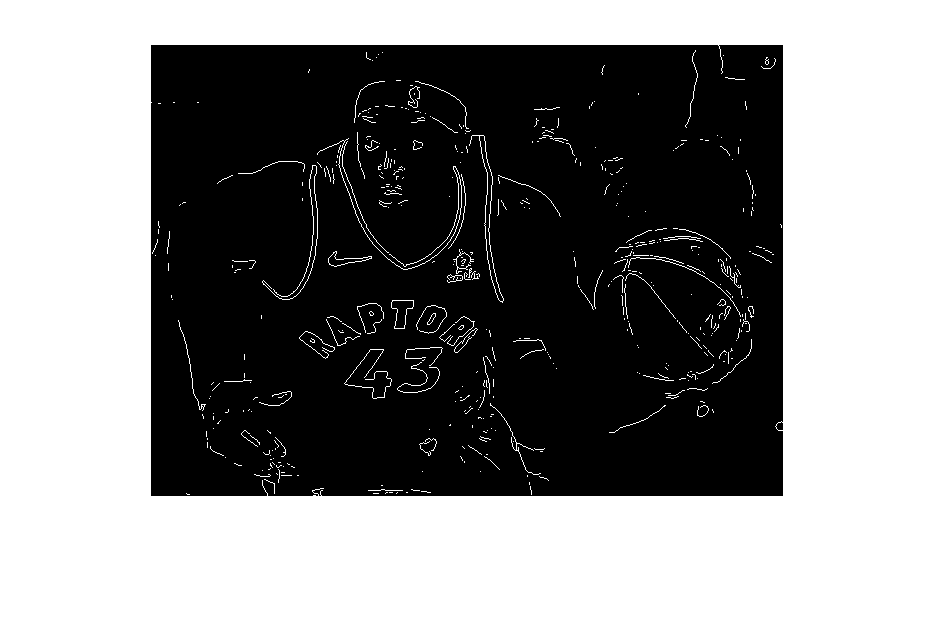

Iedge = edge(Igray,'Prewitt');
imshow(Iedge);

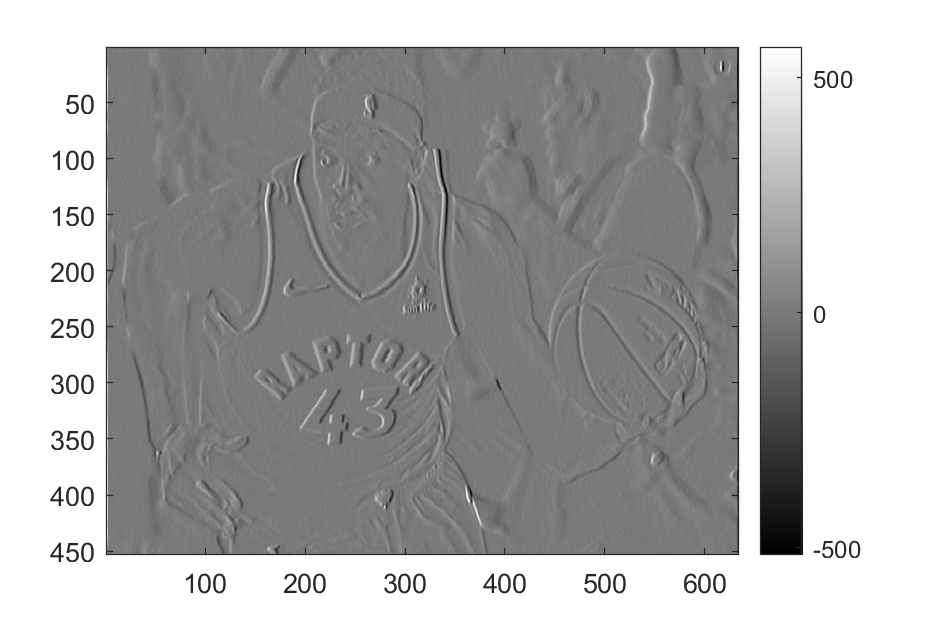

%  show gradient component in x direction 
imagesc(dIdx);   colormap("gray"); colorbar

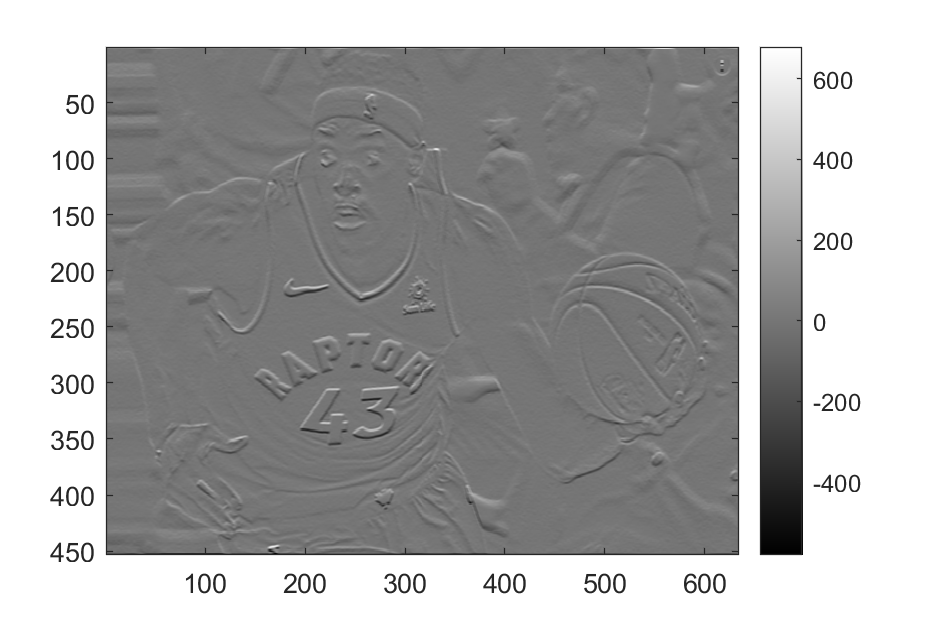

%  show gradient component in y direction 
imagesc(dIdy);  colormap("gray"); colorbar

## **Edge Detection & Filtering  (1D case)**

Let's now look at some Matlab examples of local differences and local averages that we discussed last lecture, and how they are used in edge detection.   

We first consider a step edge and examine how local difference operations.  

N = 16;
I = .2 * ones(1,N);
I(N/2:end) = 1; 

%local difference

D = [1 0 -1]  ;     % local difference
D2 = [1 -2  1];       % local difference
B = [.25 .5 .25] ;  % second derivative filter

Plot the step edge.

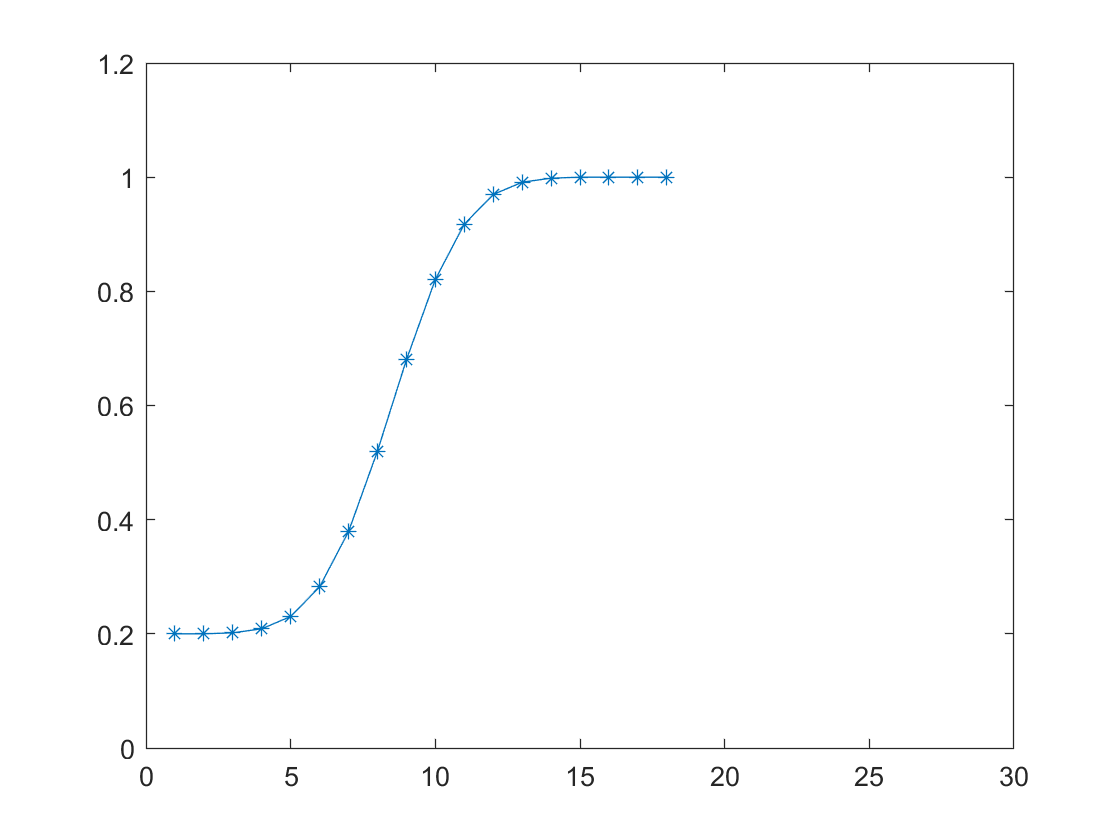

plot(I,'*-');  
axis([0 N 0 1.2])

Then plot the first derivative...

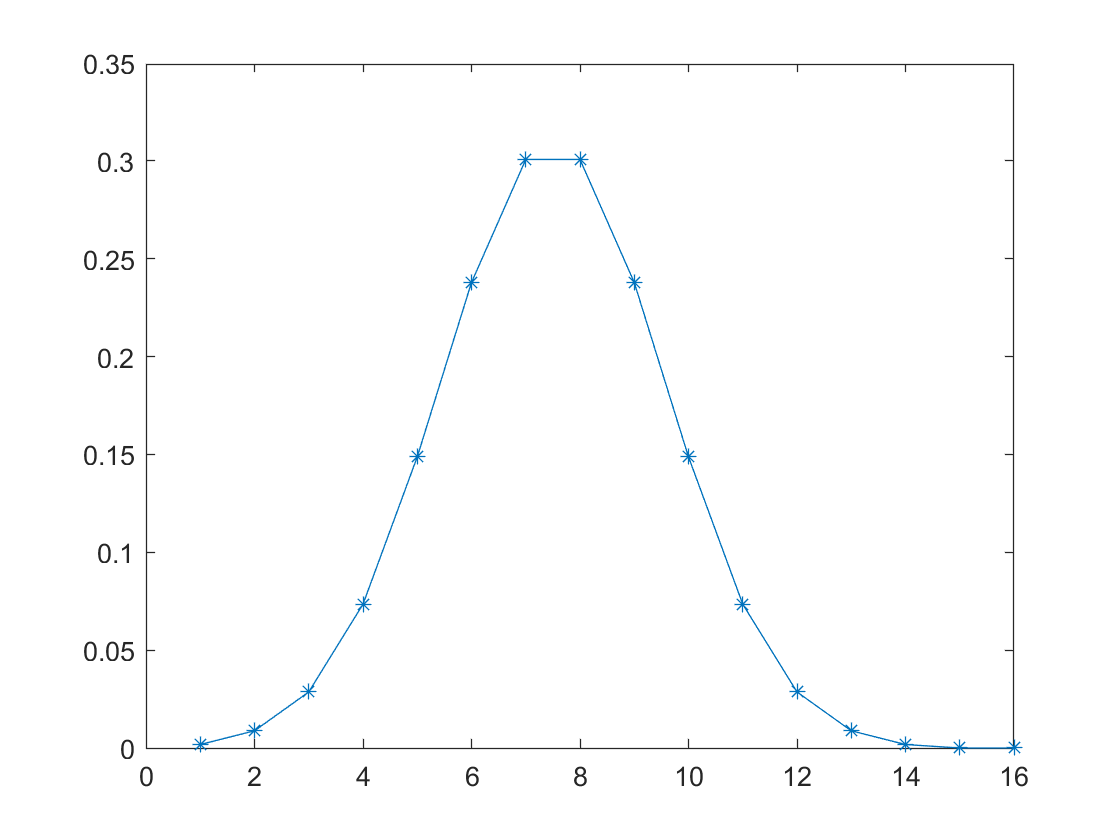

plot(conv(I,D, 'valid'),'*-');  

... and then the second derivative.

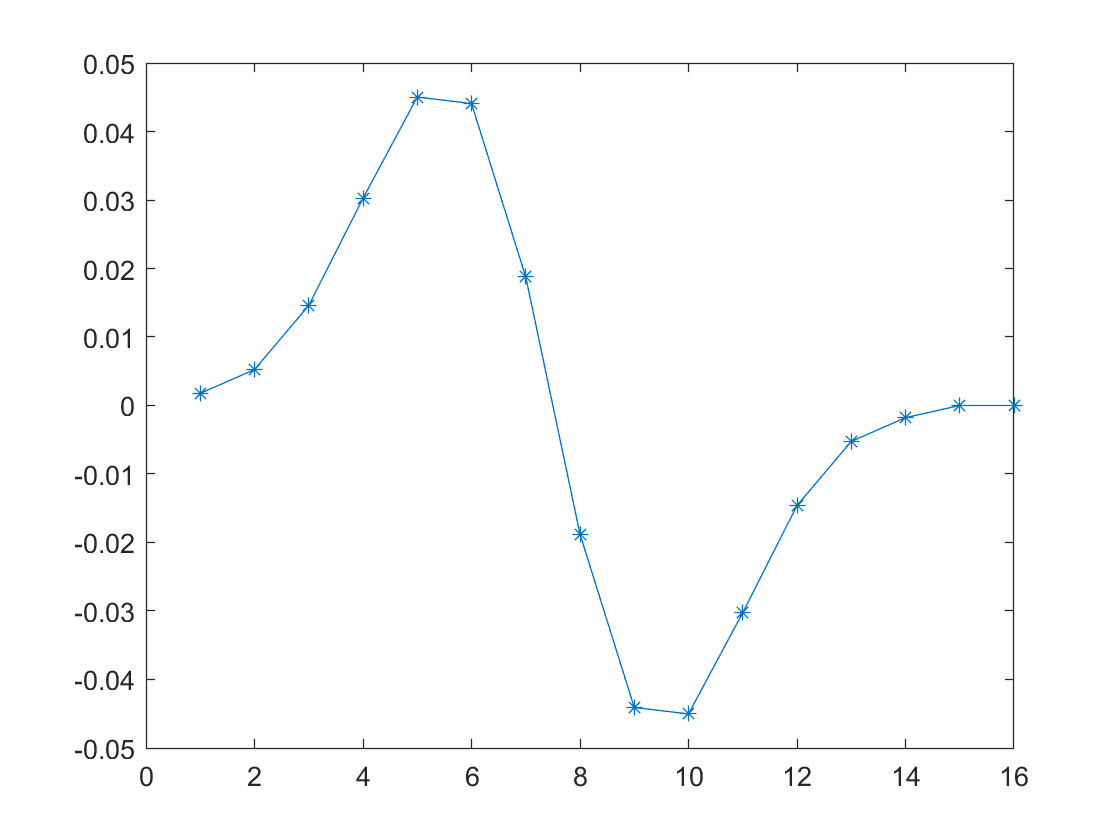

plot(conv(I,D2, 'valid'),'*-');  

Now let's blur the function with a Gaussian and repeat.     We'll make the edge bigger this time since otherwise we'll have nasty boundary effects.

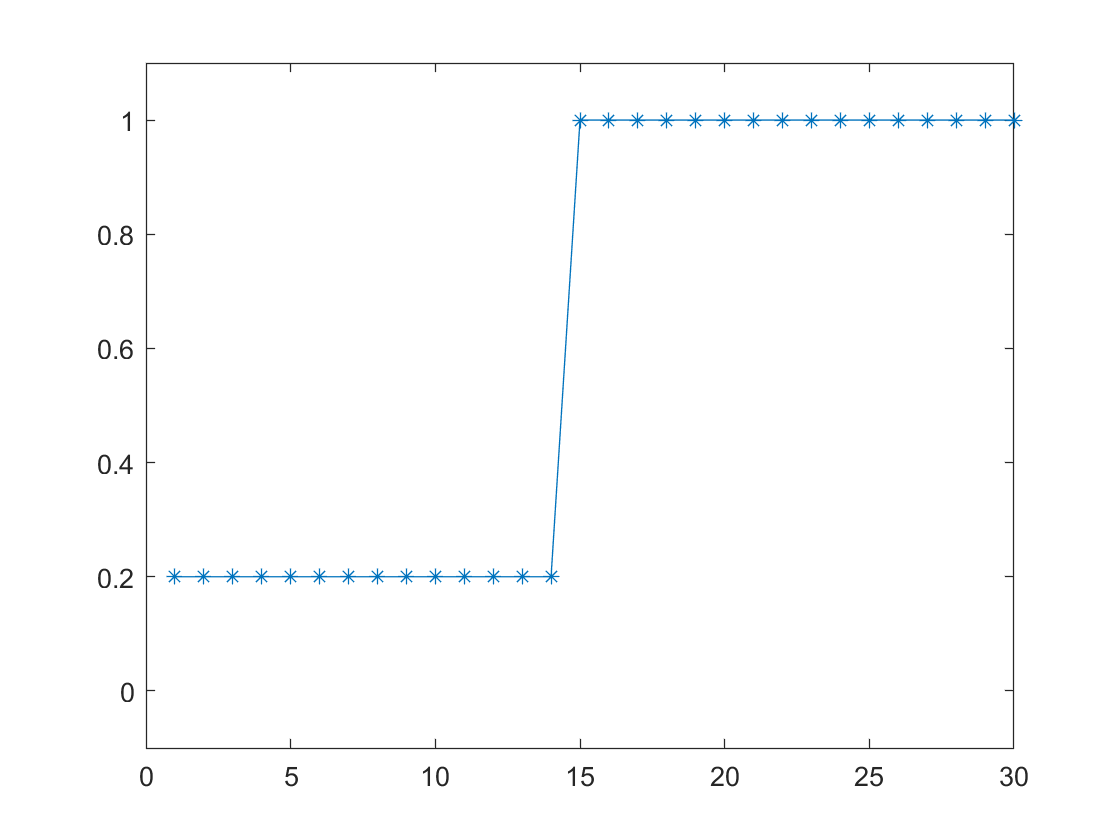

N = 30;
I = .2 * ones(1,N);
I(N/2:end) = 1; 
plot(I,'*-');
ylim([-.1, 1.1]);

sig = 2;
M = round(3*sig);
G =  exp( - (-M:M).^2/(2 * sig*sig) );
G = G/ sum(G);
I = conv(I,G, 'valid');

Plot the blurred step edge.

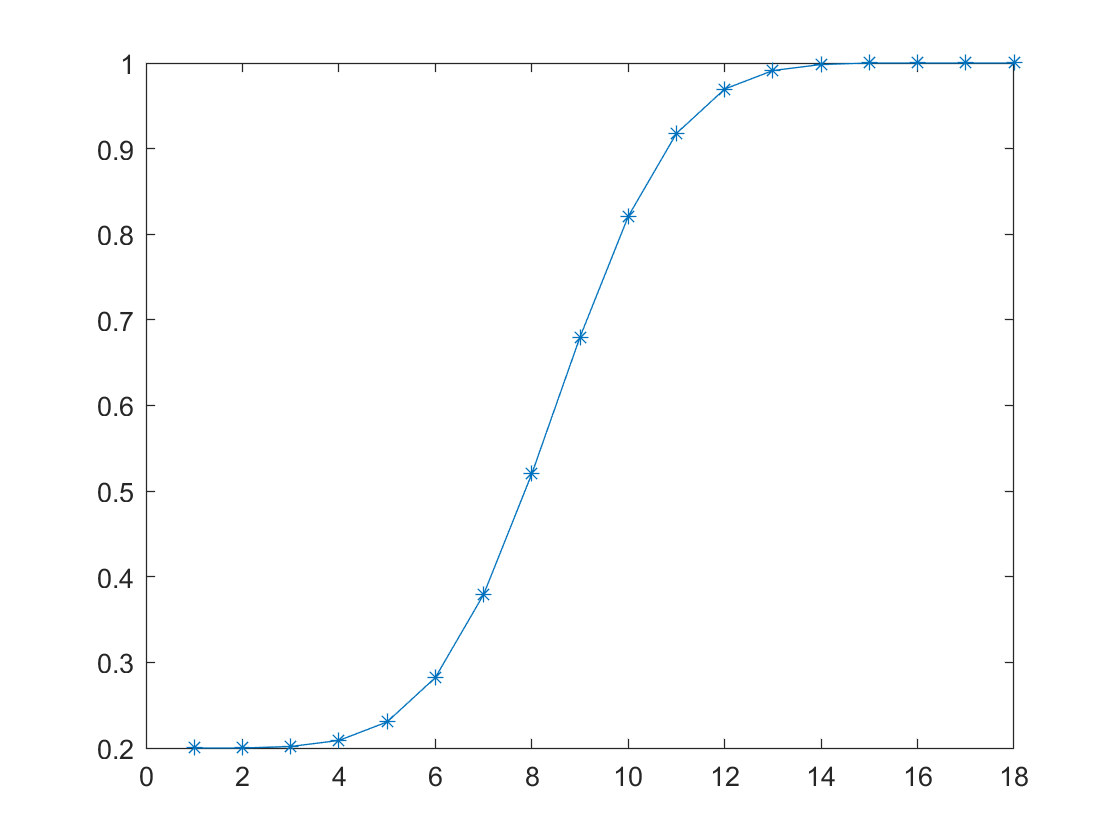

plot(I,'*-');  

Then plot the first derivative...   Note that there are fewer points plotted because of the 'valid' parameter.   So the indices of the function (x values) have a smaller range.   

plot(conv(I,D, 'valid'),'*-');  

... and then the second derivative.

plot(conv(I,D2, 'valid'),'*-');  

Let's do the same with the Gaussian filter.  I'll embed it in larger interval so it has more sample points, which will reduce the boundary effects.     

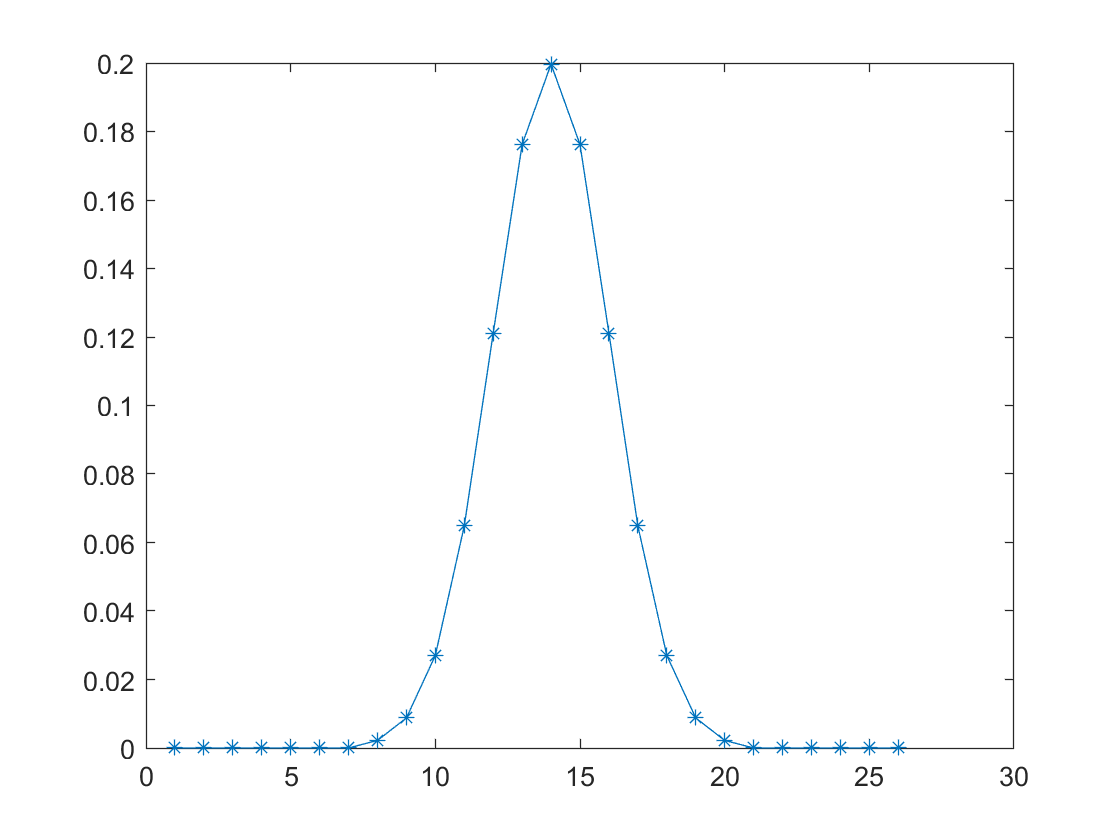

sizeG = size(G,2);
z = zeros(1,2*sizeG);
z(round(sizeG/2) + 1: round(sizeG/2) + sizeG ) = G;
G = z;
plot(G,'*-');  

Then plot the first derivative...   Note that there are fewer points plotted because of the 'valid' parameter.   So the indices of the function (x values) have a smaller range.   

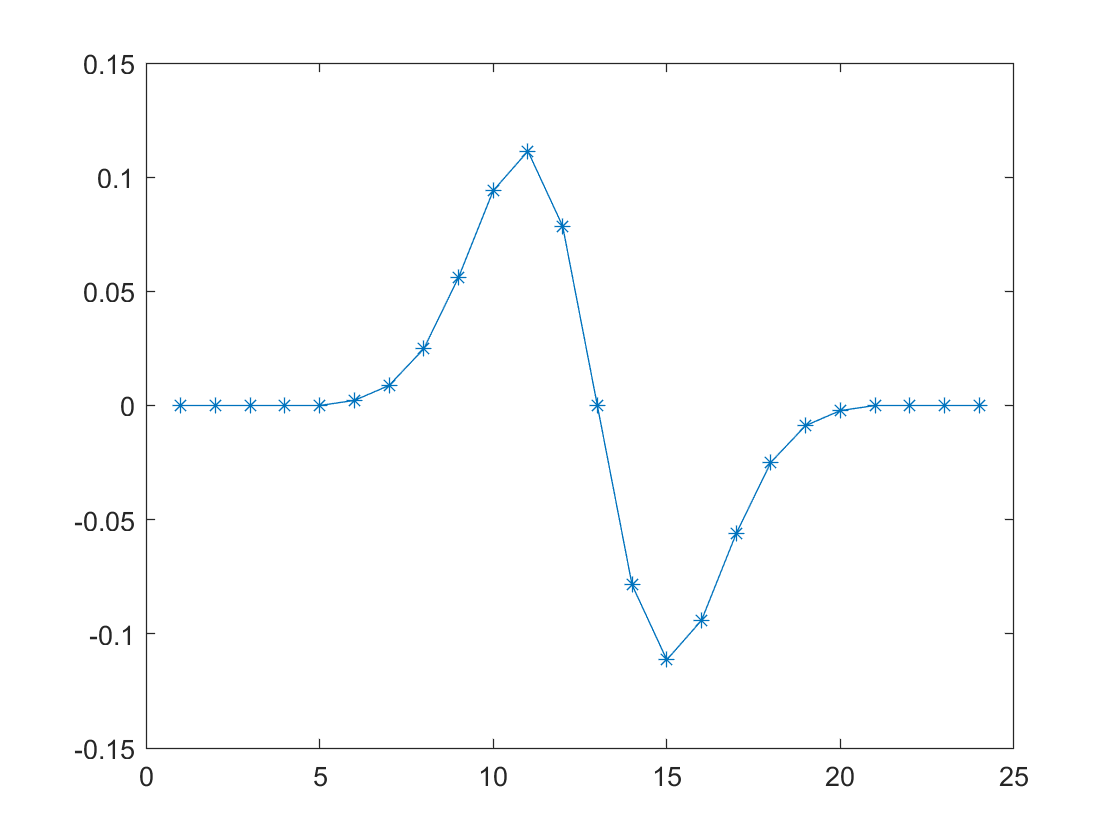

plot(conv(G,D, 'valid'),'*-');  

... and then the second derivative.

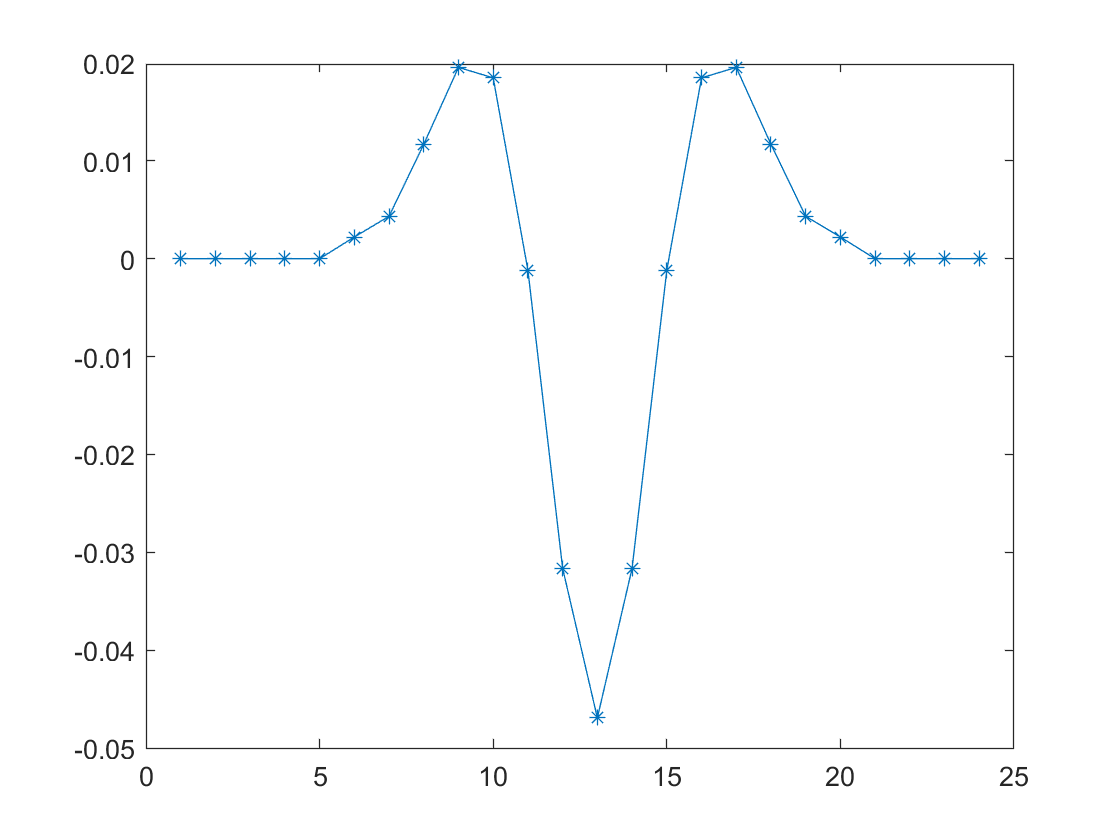

plot(conv(G,D2, 'valid'),'*-');  

## **Edge Detection & Filtering  (2D case)**

Now let's smooth the image of the basketball player (Pascal Siakem) and take the gradient component in the x direction.  Note that x means horizontal here. 

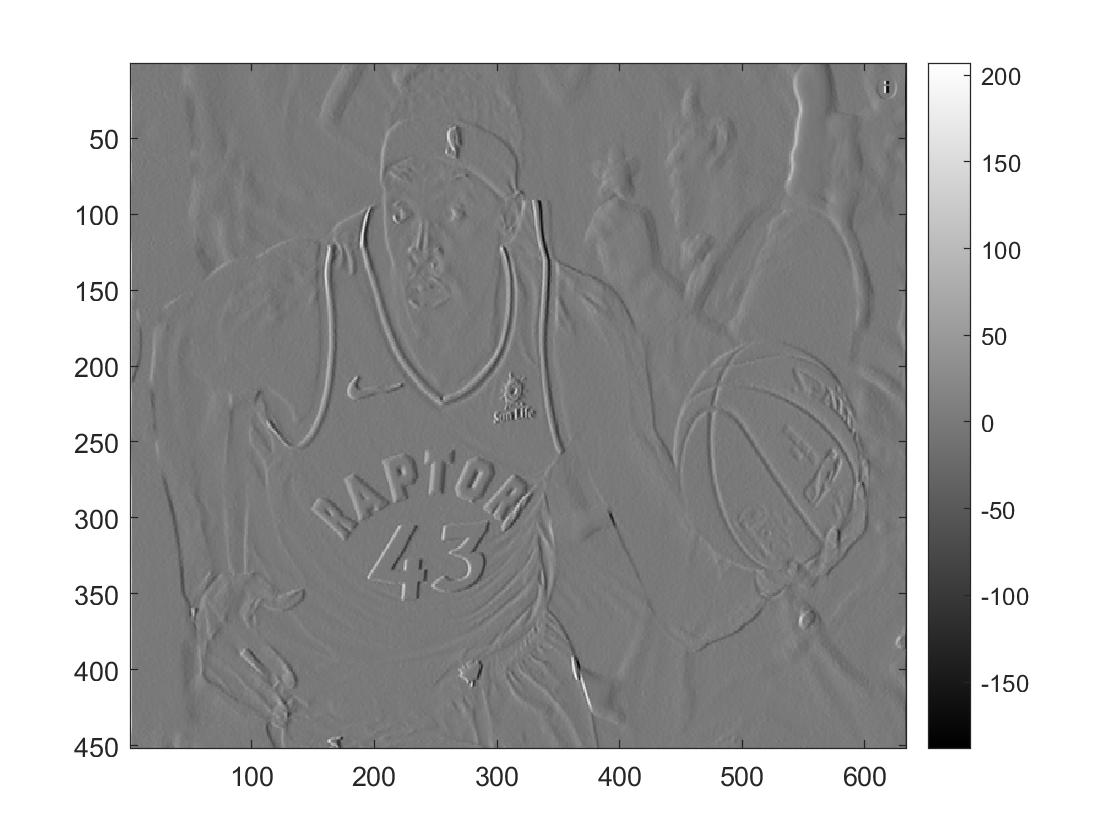

Ismooth = conv2(Igray, G, 'valid'  );  
dGIdx = conv2(Igray,  [1 0 -1]);
imagesc(dGIdx); colormap("gray");
colorbar

And now take the derivative in the y (vertical) direction.

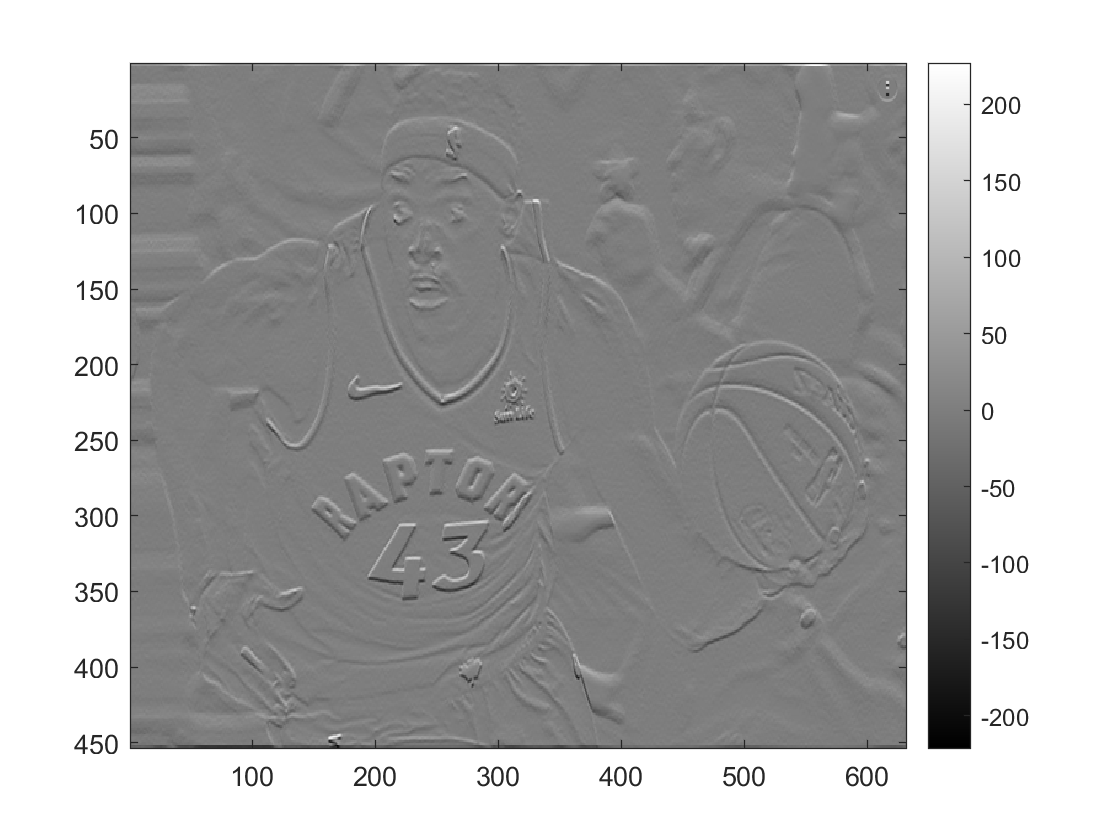

dGIdy = conv2(Igray,  [1 0 -1]');
imagesc(dGIdy); colormap(gray)
colorbar

Let's plot the magnitude of the gradient.

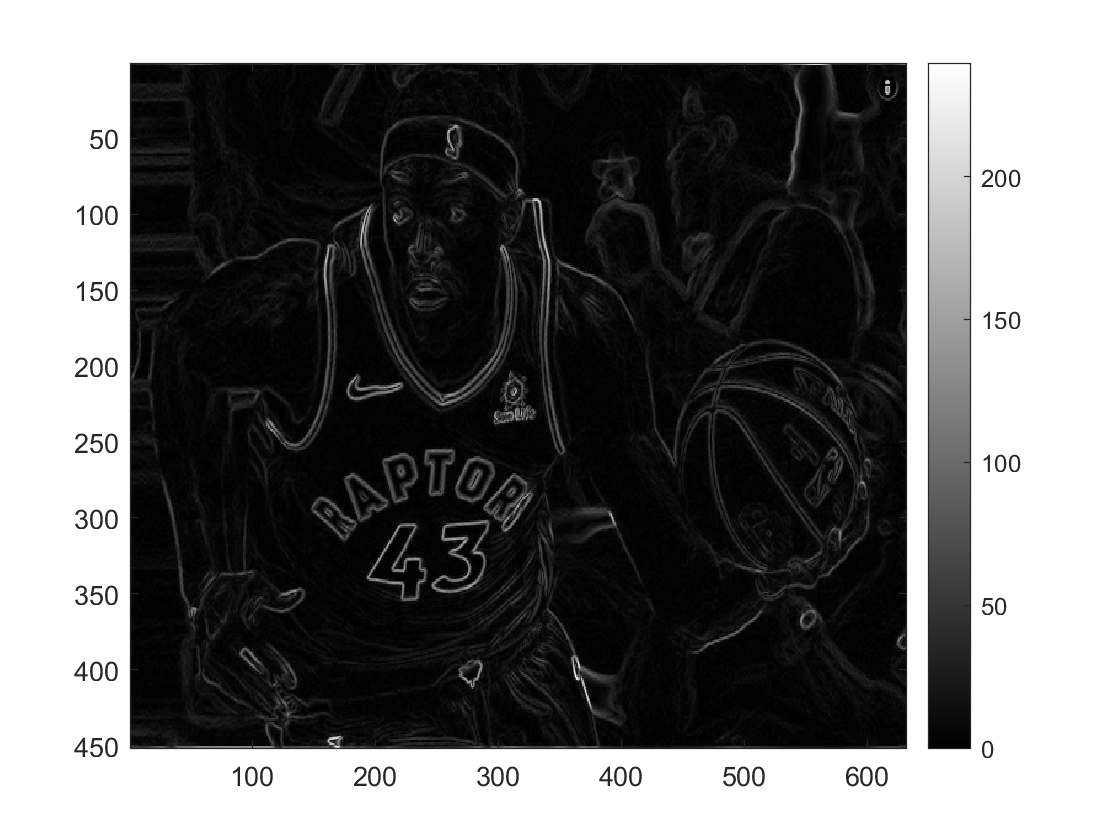

%  To combine the x and y derivatives, they'll need to be the same size
%  so I'll have to deal with boundaries.
dGIdx = dGIdx(:,2:size(dGIdx,2)-1);
dGIdy = dGIdy(2:size(dGIdy,1)-1,:);

magGrad = sqrt(dGIdx .* dGIdx + dGIdy .* dGIdy);
imagesc(magGrad); colormap(gray)
colorbar